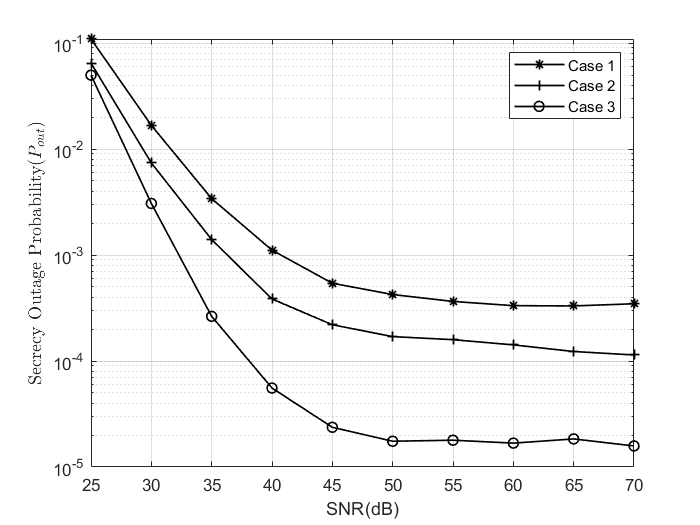

%最后一版可信个数对安全性能的影响
x=[25;30;35;40;45;50;55;60;65;70];
Onebuffer=[0.109326,0.016754,0.00341,0.001112,0.000542,0.000424,0.000365,0.000333,0.000331,0.000347];
ThreeBuffer=[0.0648,0.0074,0.0014,3.85e-4,2.2e-4,1.7e-4,1.59e-4,1.42e-4,1.23e-4,1.14e-4];
FiveBuffer=[0.0498458,0.0030711,0.000264,0.0000556,0.0000237,0.0000175,0.0000179,0.0000168,0.0000184,0.0000158];

semilogy(x,Onebuffer,'-*k','LineWidth',1);
hold on;
% 缓冲区长度为1

semilogy(x,ThreeBuffer,'-+k','LineWidth',1);
 hold on;
% 缓冲区长度为3

semilogy(x,FiveBuffer,'-ok','LineWidth',1);
hold on;
% 缓冲区长度为5


% title('');
xlabel('SNR(dB)');
ylabel('Secrecy Outage Probability($P_{out}$)','Interpreter','latex');
handle=legend('Case 1','Case 2','Case 3');
grid on